# **Squid biomass increase is not explain by rising temperature but rather loss of top predators.**

Rémy Denéchère <remy.denechere@proton.me>

## Initialisation 

clear all
clf 

% Create directory to save figure
save_dir = '../Fig/';
if ~exist(save_dir)
    mkdir(save_dir)
end 

figsave = true;

## **Ecosystem plot: **

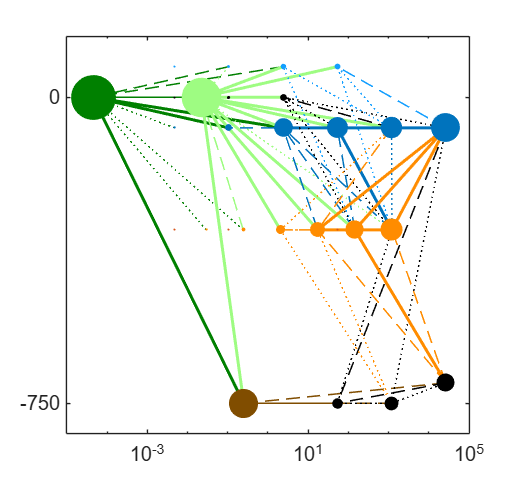

PlotEcosystem(750, 130, 0)
if figsave
    save_graph(gcf, 'pdf', [save_dir 'Ecosystem_plots'], 17, 16)
end 

## **Effect of temperature on Available Energy **

param = baseparameters();
T= linspace(0, 50, 50); 
R = 10.^([-2, -0.25, 1]) ; 

Cmax = param.Q10(1).^((T-10)/10)*param.h(1)*param.sizes(5)^-0.25

Cmax =     2.6754    2.8534    3.0433    3.2457    3.4617    3.6920    3.9377    4.1997    4.4791    4.7771    5.0950    5.4339    5.7955    6.1811    6.5924    7.0310    7.4988    7.9977    8.5299    9.0974    9.7027   10.3483   11.0368   11.7711   12.5543   13.3897   14.2805   15.2307   16.2441   17.3249   18.4776   19.7070   21.0182   22.4167   23.9082   25.4990   27.1955   29.0050   30.9349   32.9931   35.1883   37.5296   40.0267   42.6899   45.5302   48.5596   51.7905   55.2365   58.9116   62.8313


V = param.Q10(1).^((T-10)/10)*param.gamma*param.sizes(5)^-0.25

V =     9.3639    9.9869   10.6514   11.3601   12.1159   12.9221   13.7818   14.6988   15.6768   16.7199   17.8323   19.0188   20.2842   21.6339   23.0733   24.6085   26.2458   27.9921   29.8545   31.8409   33.9595   36.2190   38.6288   41.1990   43.9402   46.8638   49.9819   53.3075   56.8543   60.6371   64.6716   68.9746   73.5639   78.4585   83.6787   89.2463   95.1844  101.5175  108.2720  115.4759  123.1592  131.3536  140.0933  149.4145  159.3558  169.9586  181.2669  193.3276  206.1907  219.9097


Mc = param.Q10(1).^((T-10)/10)*param.met(1)*param.sizes(5)^-0.25

Mc =     0.5351    0.5707    0.6087    0.6491    0.6923    0.7384    0.7875    0.8399    0.8958    0.9554    1.0190    1.0868    1.1591    1.2362    1.3185    1.4062    1.4998    1.5995    1.7060    1.8195    1.9405    2.0697    2.2074    2.3542    2.5109    2.6779    2.8561    3.0461    3.2488    3.4650    3.6955    3.9414    4.2036    4.4833    4.7816    5.0998    5.4391    5.8010    6.1870    6.5986    7.0377    7.5059    8.0053    8.5380    9.1060    9.7119   10.3581   11.0473   11.7823   12.5663


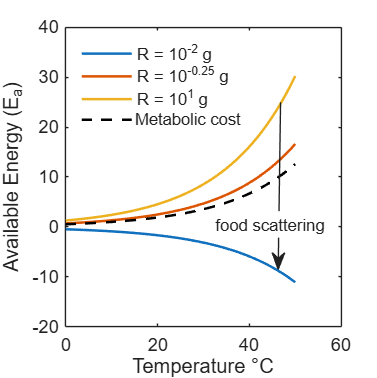


Ea = param.epsAssim * Cmax.*(V.*R'./(V.*R' + Cmax)) - Mc;

figure
plot(T, Ea, 'LineWidth', 1.5)
hold on 
plot(T, Mc, 'k--','LineWidth', 1.5)
legend('R = 10^{-2} g', 'R = 10^{-0.25} g', 'R = 10^{1} g', ...
        'Metabolic cost', 'Location','northwest', ...
        'Box','off', 'Color', 'none', 'EdgeColor', 'none')
annotation("textarrow", [0.7442 0.7379], [0.7276 0.2867], "String", "")
annotation("textbox", [0.5424 0.3704 0.3473 0.06983], "String", "food scattering")
hTextboxshape = findall(gcf,"Type","textboxshape");
hTextboxshape.EdgeColor = "none";
hTextboxshape.BackgroundColor = [1,1,1];
hTextboxshape.HorizontalAlignment = "center";

xlabel('Temperature °C')
ylabel('Available Energy (E_a)')
set(gca, 'FontSize', 11);

if figsave
    save_graph(gcf, 'pdf', [save_dir 'Ea_vs_T'], 8, 8)
end 

## **Effect of fishing intensity on squid and their predators**

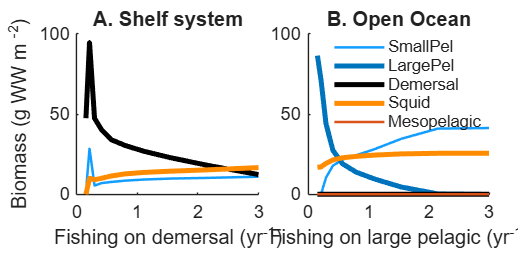

%% Biomass vs Fishing on large pelagics or Demersals 
% Simulation fishing on potential squid predators: Demersal in shallow and
% Large pelagics in deeper regions. 
if exist("fig1")
    clear fig1
end

% set up range of parameters: ---------------------------------------------
depth = [50  2000];                             % Depth in m                                              
Zoo_prod = 100;                                 % Zooplankton production (g ww m-2 yr -1)
param = baseparameters();                       % Create parameter structure
param.K = [Zoo_prod  Zoo_prod  0  0];           % Define productivity for each resouce (based on van Denderen 2021)
param.Fi = [0.1, 0, 0.1, 0.1, 0.1];             % Fishing intensity for each group with a constant fishing
FISHING = exp(linspace(log(0.2), log(3), 10));  % Define the variation of fishing intensity for large predators 
Bi = zeros(10, param.nSpecies);                 % Storage variable biomass 
k = 0;                                          % counting variable

fig1 = figure();

t = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");

for dp = 1:length(depth) % Loop depths
    param = baseparam_depth(param, depth(dp));
    k = k+1;

        for j=1:length(FISHING)
    
            % size based fishing: 
            if dp == 1 % shallow region demersal as squid predator 
                param.Fi(4) = FISHING(j);
            else % large pelagics as squid predators
                param.Fi(3) = FISHING(j);
            end
    
            % Calculate size-based fishing: 
            F = [];
            for fi = 1:param.nSpecies
                F = [F, param.Fi(fi) * (1+(param.wc(param.ix1(fi):param.ix2(fi))...
                    ./(param.wu(param.ix2(fi))*0.05)).^(-3)).^(-1)];
            end
            param.F = F';
            
            if j == 1 % Define initial condition for 1st simulation 
                param.y0 = [0.1*param.K 0.01*param.B0];           
            else % start from previous final state for later simulation 
                param.y0 = results.y(end, :) + [0.1*param.K param.B0];
            end
    
            % no meso in shallow areas. 
            if depth(dp) < param.mesop
                param.y0(param.ix1(2):param.ix2(3))=0;        
            end
           
            % Simulation of the FEISTY-squid: 
            results = poem(param);
            y = results.y; % biomass
            yend = y((end - 30):end,:);  % take values for the 40 last time steps
    
            % sum and average of biomass per species:
            for ii = 1:param.nSpecies 
                Bi(j, ii) =  sum(mean(yend(:, param.ix1(ii):param.ix2(ii))'));
            end
        end
        
        nexttile

        % plot Biomass per species  ---------------------------------------  
        Sp_plot = []; 
        hold on 
        for sp = [1, 3, 4, 5, 2]
            if sum(Bi(:, sp)) == 0 % if biomass = 0 don't plot the group. 
            else 
                % Biomass: ------------------------------------------------
                Sp_plot = [Sp_plot, sp];
                plot(FISHING, Bi(:, sp)' , '-',  'LineWidth', param.LWidth(sp),...
                'color', param.Color(sp, :))
            end 
        end
        
        if dp == 1 
            title('A. Shelf system')
            xlabel('Fishing on demersal (yr^{-1})')
        else 
            xlabel('Fishing on large pelagic (yr^{-1})')
            title('B. Open Ocean')
            legend(param.SpId{Sp_plot},'Location','best', ...
                'Box','off', 'Color', 'none', 'EdgeColor', 'none')
        end
        set(gca, 'FontSize', 11);
end
ylabel(t, 'Biomass (g WW m ^{-2})')

if figsave
    save_graph(fig1, 'pdf', [save_dir 'Fishing_Predatory_fish'], 16, 8)
end 

## Effect of large pelagic fishing on squid feeding level and mortality in the open ocean

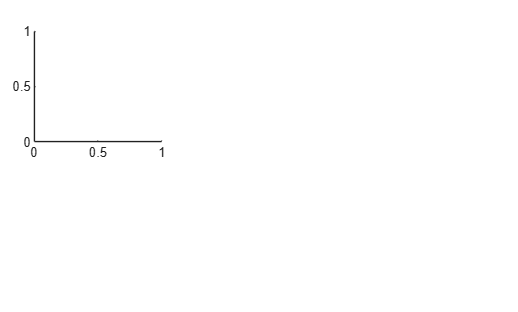

if exist("fig2")
    clear fig2
end

fig2 = figure(); 

t = tiledlayout(2, 3, "TileSpacing", "loose", "Padding", "compact");
% title(t, 'Effect of Large pelagic fishing on squid in the Open Ocean')

% set up range of parameters: ---------------------------------------------
depth = 2000;                                   % Depth in m                                           
Zoo_prod = 100;                                 % Zooplankton production (g ww m-2 yr -1)           
param = baseparameters();                       % Create parameter structure
param = baseparam_depth(param, depth);          % Create depth related parameters
param.K = [Zoo_prod  Zoo_prod  0  0];           % Define productivity for each resouce (based on van Denderen 2021)

%! Calculation at low fishing intensity : ----------------------------------
% Calculate size-based fishing: 
param.Fi = [0.1, 0, 0.1, 0.1, 0.1];             % Fishing intensity for each group with a constant fishing
F = [];
for fi = 1:param.nSpecies
    F = [F, param.Fi(fi) * (1+(param.wc(param.ix1(fi):param.ix2(fi))...
        ./(param.wu(param.ix2(fi))*0.05)).^(-3)).^(-1)];
end
param.F = F';

% Define Initial Conditions 
param.y0 = [0.1*param.K 0.01*param.B0]; 
if depth < param.mesop % no meso in shallow areas. 
    param.y0(param.ix1(2):param.ix2(3))=0;        
end
results = poem(param);

% Plot Panel A: Low fishing feeding level
nexttile

plotdiet_squid(param, results, true)

plotdiet_squid is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Rémy-PC-US2024\Documents\Work\Ph.D\Project_2\FEISTY-squid-development\Squid_abundance_Temp_vs_Fishing\src
    C:\Users\Rémy-PC-US2024\Documents\Work\Ph.D\Project_2\FEISTY-squid-development

Change the MATLAB current folder or add its folder to the MATLAB path.

ylabel('Fraction in stomach')
xlabel('Size-class ')
title('A. Low fishing')
set(gca, 'FontSize', 11)
nexttile(4, [1, 3])
plotmort_squid(param, results, '-')
title('C. Effect of large pelagic fishing on squid mortality')

%! Calculation at low fishing intensity : ----------------------------------
depth = 2000;  % 250                                                
Zoo_prod = 100;
param = baseparameters();
param = baseparam_depth(param, depth);
param.K = [Zoo_prod  Zoo_prod  0  0];

% Calculate size-based fishing: 
param.Fi = [0.1, 0, 3, 0.1, 0.1];
F = [];
for fi = 1:param.nSpecies
    F = [F, param.Fi(fi) * (1+(param.wc(param.ix1(fi):param.ix2(fi))...
        ./(param.wu(param.ix2(fi))*0.05)).^(-3)).^(-1)];
end
param.F = F';

% Define Initial Conditions 
param.y0 = [0.1*param.K 0.01*param.B0]; 
if depth < param.mesop % no meso in shallow areas. 
    param.y0(param.ix1(2):param.ix2(3))=0;        
end
results = poem(param);

% Plot Panel B: feeding level at high fishing intensity
nexttile(2)
plotdiet_squid(param, results, false)
xlabel('Size-class')
title('B. High fishing')
set(gca, 'FontSize', 11)

% Plot Panel C: Squid mortality at high fishing intensity
nexttile(4, [1, 3])
plotmort_squid(param, results, '--')
xlabel('Individual mass (g)')
leg = legend('low', 'High'); 
title(leg, 'Fishing on Large pelagic')
set(gca, 'FontSize', 11)

%! Save figure
if figsave
    save_graph(fig2, 'pdf', [save_dir 'F_mort_squid_Deep'], 16, 10)
end

## Effect of temperature

Here I simply run the zooplanton productivity sensitivity analysis of the FEISTY-squid (Denechere et al 2024) at 3 temperatures (10: temperature the model has been built on, 10-2 = 8, and 10+2 = 12) to see the variation in the system's composition with increasing temperature

%% Sensitivity on zooplankton productivity with changing temperature

if exist("fig3")
    clf(fig3)
end

fig3 = figure();

% Set up range of parameters: ---------------------------------------------
depth = [50 2000];                  % Shallow and very deep ocean (m)                                         
Zoo_prod = linspace(5, 150, 40);    % vector for Zoo productivity 
param = baseparameters();           % set up basic param
titlelab = {'A. Shelf system', 'B. Open Ocean'};                  % titles
temp = [8 12];                      % Temperature experiments (°C)
LineStyl = {':', '--'};             % Line style for temperature experiments
color_temp = [0.30, 0.75, 0.93;...  % Color for temperature effect
              0.85, 0.33 ,0.10];
Visibility_temp = {'on', 'off'};    % Define visibility for legend 
Visibility_sp = {'off', 'on'};

% Simulation and plot : ---------------------------------------------
t = tiledlayout(1, 2, TileSpacing='compact', Padding= 'compact');

for dp = 1:length(depth) %! loop depth 
    param = baseparam_depth(param, depth(dp));     % Depth specific parameters
    Bi = zeros(length(Zoo_prod), param.nSpecies);  % Storage variable biomass to compare with other temperature
    nexttile                                       % Change subplot location for each depth
    param = baseparam_temp(param, 4, 10);          % Temperature ref     

    for i = 1:length(Zoo_prod) %! Loop zooplankton productivity
        param.K =  [Zoo_prod(i), Zoo_prod(i), 0, 0];  % Gives zoo prod to param

        if i == 1 % 1st run Initial condition
            param.y0 = [0.1*param.K 0.01*param.B0];           
        else % Start from previous final state. 
            param.y0 = results.y(end, :) + [0.1*param.K param.B0];
        end
        
        if(param.bottom <= param.mesop) % No mesopelagic if depth inf to 200m
                param.y0(param.ix1(2):param.ix2(2)) = 0;
        end

        results = poem(param);                    % Run model
        yend = mean(results.y((end - 40):end,:)); % Take mean biomass for the last 41 time steps

        % Average of biomass then Sun of biomass per functional group 
        for ii = 1:param.nSpecies 
            Bi(i, ii) =  sum(yend(:,param.ix1(ii):param.ix2(ii)));
        end 
    end% end loop zoo prod
    
    % Compare 10°C with other temperature: ----------------------------
    for T = 1:length(temp)% loop temperature 
        param = baseparam_temp(param, 4, temp(T));       % Temperature effect on physiological parameters 
                                                         % (4 same temperature in the whole whater column) 
        Bi_T = zeros(length(Zoo_prod), param.nSpecies);  % Storage variable biomass to compare with other temperature  
                                            
        for i = 1:length(Zoo_prod) %! Loop zooplankton productivity
            param.K =  [Zoo_prod(i), Zoo_prod(i), 0, 0]; % Gives zoo prod to param
    
            if i == 1 % 1st run Initial condition
                param.y0 = [0.1*param.K 0.01*param.B0];           
            else % Start from previous final state. 
                param.y0 = results.y(end, :) + [0.1*param.K param.B0];
            end
            
            if(param.bottom <= param.mesop) % No mesopelagic if depth inf to 200m
                    param.y0(param.ix1(2):param.ix2(2)) = 0;
            end
    
            results = poem(param);                    % Run model
            yend = mean(results.y((end - 40):end,:)); % Take mean biomass for the last 41 time steps
    
            % Sun of biomass per functional group 
            for ii = 1:param.nSpecies 
                Bi_T(i, ii) =  sum(yend(:,param.ix1(ii):param.ix2(ii)));
            end 
        end 
        
        % Plot Biomass per species 10°C: ----------------------------------
        hold on 
        for sp = 1:param.nSpecies %! Plot biomass for each group  
            ciplot(Bi(:, sp)', Bi_T(:, sp)', Zoo_prod, 'colour',  color_temp(T,:), ...
                'alpha', 0.5, 'Linestyle', 'none', 'VisLegend', 'off');
        end
        ciplot(sum(Bi, 2), sum(Bi_T, 2), Zoo_prod, 'colour',  color_temp(T,:), ...
                'alpha', 0.5, 'Linestyle', 'none', 'VisLegend', Visibility_temp{dp});
    end % end loop temperature

    % Plot Biomass per species 10°C: ----------------------------------
    
    for sp = 1:param.nSpecies %! Plot biomass for each group                  
        plot(Zoo_prod, Bi(:, sp)', 'LineWidth', param.LWidth(sp), ... 
            'Color', param.Color(sp,:), 'HandleVisibility', Visibility_sp{dp})
    end
    plot(Zoo_prod, sum(Bi'), '--k', 'HandleVisibility', Visibility_sp{dp})
    hold off
    title(titlelab{dp})
    % legend: 
    if dp ==1
        legend({'-2°C', '+2°C'} , 'Location', 'northeast', ...
            'Color','none', 'EdgeColor', 'none')
    else 
        legend([param.SpId{:}, {'Total'}] , 'Location', 'northwest', ...
            'Color','none', 'EdgeColor', 'none')
    end 
end
    
xlabel(t, 'Zooplankton productivity (g m^{-2} yr^{-1})')
ylabel(t, 'Biomass (g m^{-2})')

%! Save figure
if figsave
    save_graph(fig3, 'pdf', [save_dir 'Sens_Biomass_productivity_temp'], 16, 10)
end